function z=calcz(N,beta)
k=1:N;
z=(1./(1-exp(-k.*beta))).^3;%equation 7.18
end

function Z=canonicrecursion(z)
N=length(z);
Z=zeros(1,N+1);
Z(1)=1;
for M = 1:N
    Z(M+1)=sum(Z(1:M).*z(M:-1:1))/M;
end
end

function m=directcycles(Z,z)
N=length(z);
m=zeros(1,N);
M=N;
while M>0
    kset=z(1:M).*Z(M:-1:1);%set from which to sample k
    kset=kset/sum(kset);%normalizing for sampling
    k=find(cumsum(kset)>=rand(),1,'first');
    M=M-k;
    m(k)=m(k)+1;
end
end

%as given on webiste, edited to work in matlab
function x=lharmonic(dtau,N)
beta=N*dtau;
x=zeros(1,N);
x(1)=randn()/sqrt(2*tanh(beta/2));
for k = 1:N-1
    U1=1/tanh(dtau)+1/tanh((N-k)*dtau);
    U2=x(k)/sinh(dtau)+x(1)/sinh((N-k)*dtau);
    xmean=U2/U1;
    sigma=1/sqrt(U1);
    x(k+1)=xmean+sigma*randn();
end
end

function x=dhb(z,Z,dtau)
N=length(z);
x=zeros(1,N);
m=directcycles(Z,z);
l=0;
for k=1:N
    if m(k)>0
        for i=1:m(k)
            x(l+1:l+k)=lharmonic(dtau,k);
            l=l+k;
        end
    end
end
end

Bosons are indistinguishable, so we must account for particles exchanging with one another. Algorithm dhb takes as input z, Z and dtau. z represents the statistical weight of a particle forming a loop of lenght k. We then use a recurrence relation to caluculate the partition function Z. With these values we use direct cycles to determine what loop size each particle belongs to in a probabilistic manner. Once we have determined the cycle structure we use the levy harmonic algorithm to determine their positions

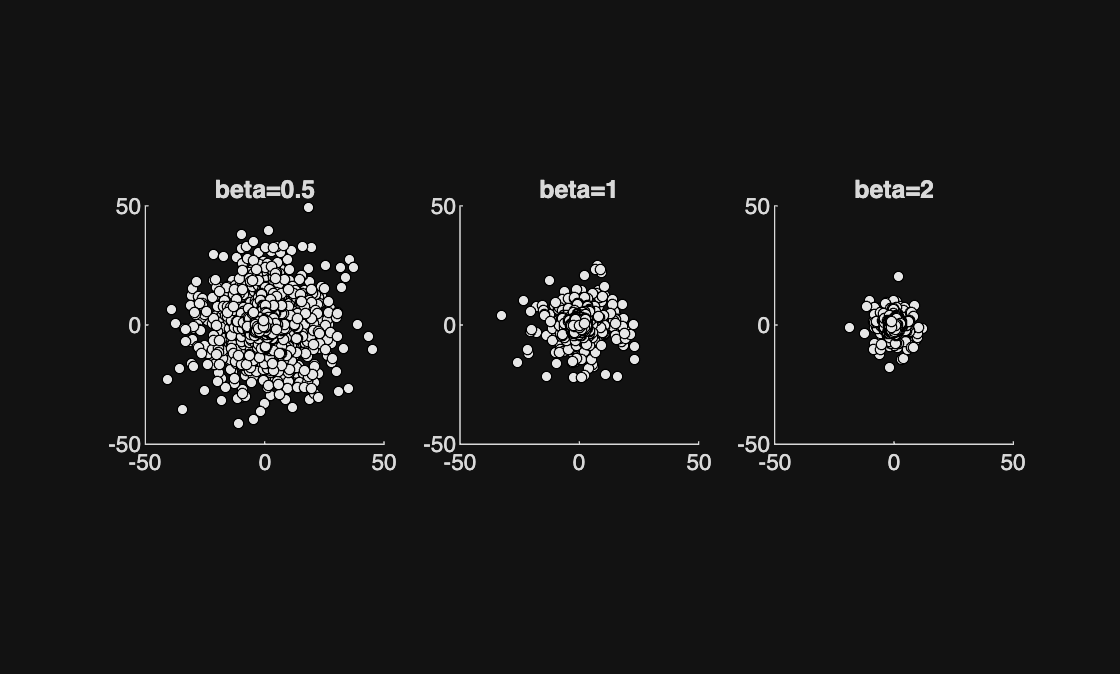

N=100;
nevents=50;
betas=[0.5,1,2];
figure;
for j =1:3
    beta=betas(j);
    dtau=beta/N;
    z=calcz(N,beta);
    Z=canonicrecursion(z);
    x=zeros(nevents,N);
    y=zeros(nevents,N);
    for i=1:nevents
        x(i,:)=dhb(z,Z,dtau);
        y(i,:)=dhb(z,Z,dtau);
    end
    subplot(1,3,j)
    scatter(x(:),y(:),15,'MarkerEdgeColor','k','MarkerFaceColor',[0.9 0.9 0.9]); 
    title(['beta=',num2str(beta)]);
    axis square;
    xlim([-50 50]);
    ylim([-50 50]);
end

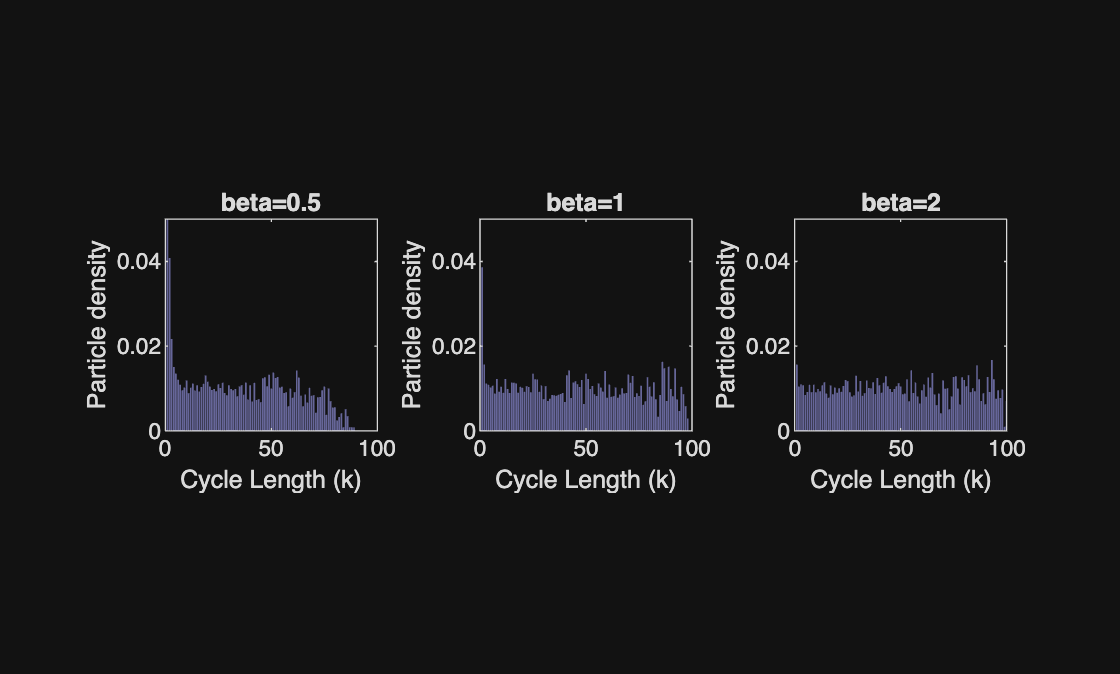

N=100;
nevents=1000;
betas=[0.5,1,2];
figure;
for j=1:3
    beta=betas(j);
    z=calcz(N,beta); 
    Z=canonicrecursion(z);
    mout=zeros(1,N);
    for i=1:nevents
        m=directcycles(Z,z);
        mout=mout+m;
    end
    mavg=mout/nevents;
    k=1:N;
    cycleweight=(k.*mavg)/N;
    subplot(1, 3, j)
    bar(k, cycleweight, 'FaceColor', [0.4 0.4 0.6], 'EdgeColor', 'none');
    title(['beta=', num2str(beta)]);
    xlabel('Cycle Length (k)');
    ylabel('Particle density');
    axis square;
    xlim([0 N]);
    ylim([0 0.05])
end

For high temp (small beta) the distribution is dominated by very short cycles. As we increase beta this spike eventually 'flattens' out.

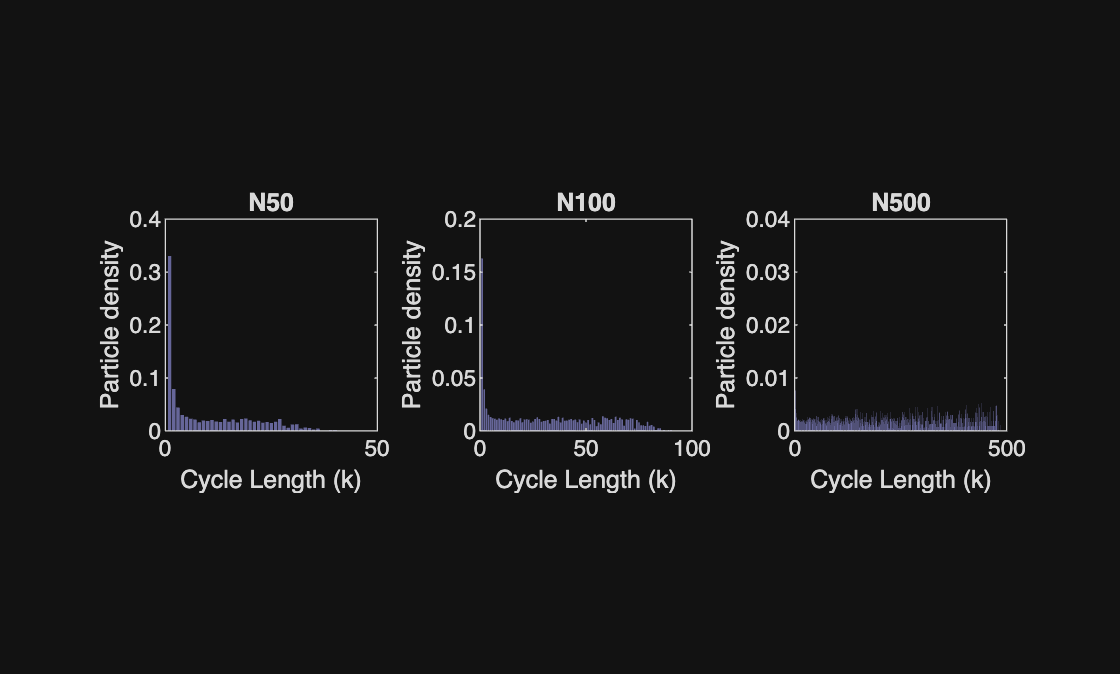

Ns=[50,100,500];
nevents=1000;
beta=0.5;
figure;
for j=1:3
    N=Ns(j);
    z=calcz(N,beta);  
    Z=canonicrecursion(z);
    mout=zeros(1,N);
    for i=1:nevents
        m=directcycles(Z,z);
        mout=mout+m;
    end
    mavg=mout/nevents;
    k=1:N;
    cycleweight=(k.*mavg)/N;
    subplot(1, 3, j)
    bar(k, cycleweight, 'FaceColor', [0.4 0.4 0.6], 'EdgeColor', 'none');
    title(['N', num2str(N)]);
    xlabel('Cycle Length (k)');
    ylabel('Particle density');
    axis square;
    xlim([0 N]);
end

We see the same trend as before, where the distribution of the cycle lenghts is dominated by small loops for small N, and as N increases the distribution flattens out. These graphs show that for a temperature that is too hot for condensation to occur for a set amount of particles is actually sufficient enough if we increase N accordingly. So as N tends to infinity the critical temperature also approaches infinity.